# Principal Component Analysis (PCA)

Lorem Ipsum

⚠️ Work in progress 

clc
clear
close all

## Building dataset

Genero distribuzione normale di $n$ punti random con deviazione standard $\sigma$ e media $\mu$. 

In `MATLAB` è possibile generare delle distribuzioni normali utilizzando la funzione `randn();` tale funzione restituisce una distribuzione centrata sullo zero ($\mu = 0$) e deviazione standard unitaria ($\sigma=1$). Qualora si volessero modificare tali parametri sarà sufficiente moltiplicare l'output per la $\sigma$ voluta e aggiungere $\mu$ al risultato del prodotto. La sintassi sarà quindi del tipo `data = sigma.*randn(n,2) + mu`. Si noti che il numero `2` come argomento della funzione `randn()` indica il numero di colonne da generare: una per le ascisse $x$, una per le ordinate $y$.

Nel caso in cui si volesse specificare una deviazione standard differente per le $x$ e per le $y$ per modificare la forma della distribuzione, è possibile porre $\sigma = ( \sigma_x , \sigma_y)$.

In tal modo, se $P$ è la matrice output della funzione `randn()` 


$$P=\pmatrix{x_1 & y_1 \cr x_2 & y_2 \cr ... & ... \cr  x_n & y_n}$$


sarà sufficiente effettuare moltiplicazione elemen-wise (prodotto di Hadamard) $\sigma \odot P$ per modificare la deviazione standard della distribuzione:


$$\sigma \odot P = \pmatrix{\sigma_x & \sigma_y} \odot \pmatrix{x_1 & y_1 \cr x_2 & y_2 \cr ... & ... \cr  x_n & y_n} =\pmatrix{ \sigma_x x_1 & \sigma_y y_1 \cr \sigma_x x_2  & \sigma_y y_2 \cr ... & ... \cr  \sigma_x x_n & \sigma_y y_n}$$


In `MATLAB` la sintassi da utilizzare è `sigma.*randn(n,2)` dove `sigma = [2 0.9]` con $\sigma_x = 2$, $\sigma_y = 0.9$.

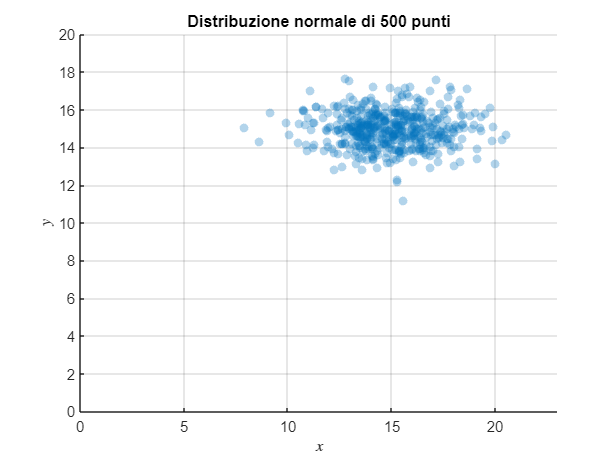

n = 500;                % numero di punti
sigma = [2 0.9];        % deviazione standard su x e su y
mu = 15;                % media

% genero set di dati
data = sigma.*randn(n,2) + mu;

x = data(:,1);
y = data(:,2);

endpoints = find_endpoints(data,2);     % limiti degli assi
alpha = .3;                             % opacità dei punti

% rappresento distribuzione
figure;
scatter(x,y,'o','filled','MarkerEdgeColor','none','MarkerFaceAlpha',alpha)
xlim([0 endpoints(2)])
ylim([0 endpoints(4)])
xlabel("$x$",'Interpreter','latex')
ylabel("$y$",'Interpreter','latex')
title(sprintf("Distribuzione normale di %d punti",n))
grid on
box off
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';

Adesso applichiamo una **trasformazione lineare** alle distribuzioni dei dati. Se la matrice della trasformazione $T$ è


$$T=\pmatrix{1 & 1 \cr -1 & 1}$$


e il dataset contiene gli $n$ punti $P$


$$P=\pmatrix{x_1 & y_1 \cr x_2 & y_2 \cr ... & ... \cr  x_n & y_n}$$


allora i punti trasformati $P'$ si otterranno eseguendo il prodotto matriciale $T P^T$ dove $P^T$ indica la trasposta di $P$


$$P' =T P^T= \pmatrix{1 & 1 \cr -1 & 1} \pmatrix{x_1 & x_2 & ... & x_n \cr y_1 & y_2 & ... & y_n}$$


% creo matrice trasformazione
% linear_trasformation = [1 1; -1 1]
linear_trasformation = rand(2,2)

linear_trasformation =     0.1336    0.7411
    0.0166    0.1898



% applico trasformazione
transformed_data = (linear_trasformation*(data'))'

transformed_data =    12.2076    2.8771
   12.7623    3.0243
   13.1453    3.1193
   11.7652    2.7515
   13.2342    3.1068
   11.7873    2.7696
   11.5075    2.6944
   12.0457    2.8336
   13.1519    3.1240
   13.5176    3.1823


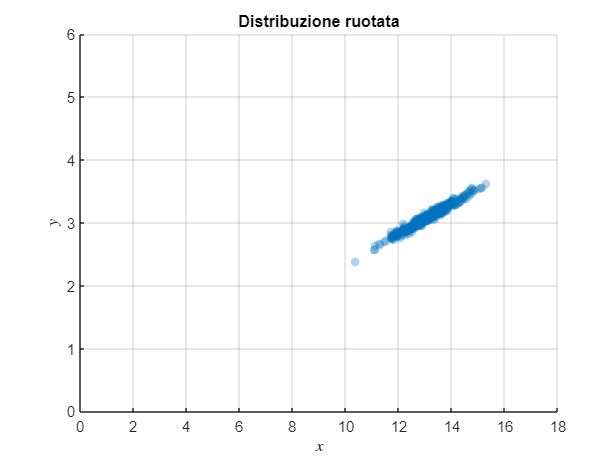


x = transformed_data(:,1);
y = transformed_data(:,2);

endpoints = find_endpoints(transformed_data,2);     % limiti degli assi

% rappresento distribuzione ruotata
scatter(x,y,'o','filled','MarkerEdgeColor','none','MarkerFaceAlpha',alpha)
xlim([0 endpoints(2)])
ylim([endpoints(3) endpoints(4)])
xlabel("$x$",'Interpreter','latex')
ylabel("$y$",'Interpreter','latex')
grid on
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
title("Distribuzione ruotata")

## Centering data

% centro i dati sottraendo la media
dfm = mean(transformed_data)

dfm =    13.0849    3.0871


B = transformed_data-dfm

B =    -0.8774   -0.2100
   -0.3227   -0.0628
    0.0603    0.0322
   -1.3198   -0.3356
    0.1493    0.0197
   -1.2977   -0.3175
   -1.5774   -0.3926
   -1.0392   -0.2535
    0.0670    0.0370
    0.4326    0.0952


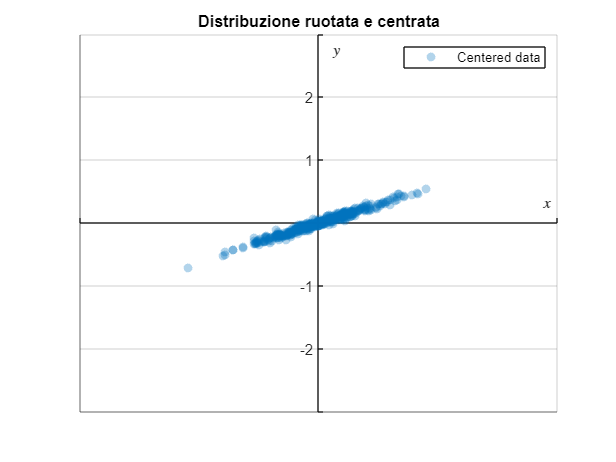


% rappresento distribuzioni centrate
scatter(B(:,1),B(:,2), 'filled', 'MarkerFaceAlpha', alpha,'MarkerEdgeColor','none')
title("Distribuzione ruotata e centrata")
xlabel("$x$",'Interpreter','latex')
ylabel("$y$",'Interpreter','latex')
legend("Centered data")
axis(find_endpoints(B,2))
box off
grid on
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';

## Riferimenti matematici

I *Principal components* sono degli assi su cui è possibile proiettare i dati massimizzando la varianza. Tali assi sono definiti come gli autovettori della matrice di covarianza $\Sigma$


$$\Sigma = \pmatrix{var(\bar{x}) & cov(\bar{x},\bar{y}) \cr cov(\bar{y},\bar{x}) & var(\bar{y})}$$


Si noti che la diagonale della matrice $\Sigma$ contiene le varianze $\sigma_i$ che in `MATLAB` è possibile estrarre utilizzando la funzione `diag()`.

Per quanto riguarda gli autovettori e gli autovalori, questi possono essere determinati utilizzando la sintassi `[autovettori, autovalori] = eig(C)` dove `C` è la matrice di covarianza. Noi saremo interessati all'autovalore massimo (che sarà utile per PC1).

C = cov(B)

C =     0.5352    0.1280
    0.1280    0.0317


[evec,eval]=eig(C)

evec =     0.2331   -0.9725
   -0.9725   -0.2331


eval =     0.0010         0
         0    0.5659


[emax,id_emax]= max(diag(eval));
[emin,id_emin]= min(diag(eval));

% la posizione dell'autovettore massimo sarà utile per estrarre la colonna
% degli autovettori pari a id_emax
PC1 = evec(:,id_emax)

PC1 =    -0.9725
   -0.2331


PC2 = evec(:,id_emin)

PC2 =     0.2331
   -0.9725



% proiettiamo i dati B su PC1 eseguendo il prodotto scalare
z = B*PC1

z =     0.9022
    0.3284
   -0.0662
    1.3616
   -0.1497
    1.3359
    1.6255
    1.0697
   -0.0738
   -0.4429



% otteniamo coordinate
projected_B = z*PC1'

projected_B =    -0.8773   -0.2103
   -0.3194   -0.0765
    0.0643    0.0154
   -1.3241   -0.3173
    0.1456    0.0349
   -1.2992   -0.3113
   -1.5807   -0.3788
   -1.0403   -0.2493
    0.0717    0.0172
    0.4307    0.1032


p_b_2 = (B*PC2)*PC2';

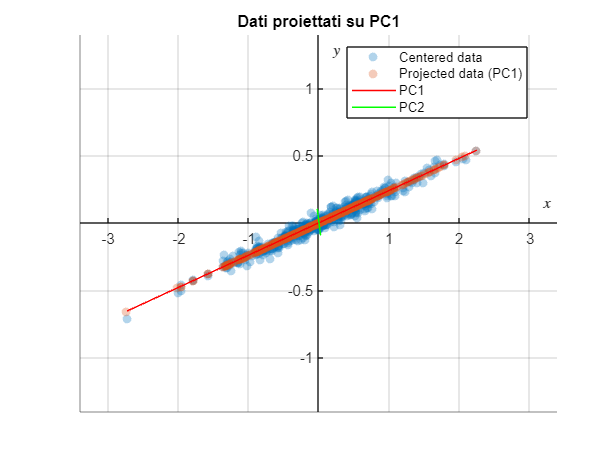

% rappresento i dati
scatter(B(:,1),B(:,2), 'filled', 'MarkerFaceAlpha', alpha,'MarkerEdgeColor','none')
hold on
scatter(projected_B(:,1),projected_B(:,2), 'filled', 'MarkerFaceAlpha', alpha,'MarkerEdgeColor','none')
plot(projected_B(:,1),projected_B(:,2),'r-','LineWidth',1)
plot(p_b_2(:,1),p_b_2(:,2),'g-','LineWidth',1)
hold off
grid on
legend("Centered data","Projected data (PC1)","PC1","PC2",'Location','best')
axis(find_endpoints(projected_B,.4))
xlabel("$x$",'Interpreter','latex')
ylabel("$y$",'Interpreter','latex')
title("Dati proiettati su PC1")
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';

## SVD

come fare tutto con SVD?

## Note

Questo documento è stato generato convertendo in markdown un `MATLAB` livescript utilizzano il tool `livescript2markdown`

% esporto in md
livescript2markdown("pca_v2.mlx","../README.md","AddMention",true,"Format","github")

Coverting latex to markdown is complete
README.md
Note: Related images are saved in README_images


ans = "C:\Users\Dennis Angemi\Documents\GitHub\machine-learning-for-physics\2_principal_component_analysis\README.md"

## Functions

function endpoints = find_endpoints(data_array,margin)
    endpoints = [floor(min(data_array(:,1)))-margin ceil(max(data_array(:,1)))+margin floor(min(data_array(:,2)))-margin ceil(max(data_array(:,2)))+margin];
end